# 回帰ネットワークの構築と学習

目標座標(x, y)を推定する回帰モデルを学習する。

## 初期化

clear; close all; clc; rng('default');

## ファイル名を指定

動画とラベルデータのファイル名を指定する

fileName = 'exportedLabels.mat';
videoName = 'robotTrain.avi';
doTraining = true;
doDesignWithDND = true;

## ラベルデータの読み込み

ワークスペース変数にラベルデータをロード

load(fileName);

## ラベルデータ保存用のフォルダを作成

[~,filename,~] = fileparts(gTruth.DataSource.Source);
dataFolder = fullfile(pwd,filename);
[~,~,~] = rmdir(dataFolder,'s');
[~,~,~] = mkdir(dataFolder);

## ラベリングした目標座標の座標を抽出

labelData = gTruth.LabelData.WhiteLine;
validVideoIndex =  ismember(gTruth.LabelData.Time,gTruth.DataSource.TimeStamps);
Y = zeros(length(labelData),2);
for i = 1:length(labelData)
    Y(i,:) = labelData{i}{1}(end,:);
end

## 動画から画像を抽出

ラベル付けされている静止画を抜き出し、画像ファイルとして保存

(動画が大きい場合はメモリを多く消費するため100枚以下にする。デフォルトは21枚。)

v = VideoReader(videoName);
wh = [v.Width v.Height];

videoIndex = find(validVideoIndex);
for k = 1:numel(videoIndex)
    video = read(v,videoIndex(k));
    imwrite(video,fullfile(dataFolder,num2str(int32(k),'image_%05d.png')));
end

% 全データを可視化
imds = imageDatastore(dataFolder);
figure;
montage(imds);

% 目標座標が画像中心を原点とし、長い辺が[-1 1]になるように正規化
Y = (Y - wh(1)/2) ./ (wh(1)/2)

## データセットを学習用とテスト用に分ける

rng(0);
shuffledIndices = randperm(imds.numpartitions);
idx = length(shuffledIndices) - 4; % 4枚をテスト用にする
trainImds = imageDatastore(imds.Files(shuffledIndices(1:idx)));
testImds = imageDatastore(imds.Files(shuffledIndices(idx+1:end)));
trainArrayDs = arrayDatastore(Y(shuffledIndices(1:idx),:));
testArrayDs = arrayDatastore(Y(shuffledIndices(idx+1:end),:));

% 画像と目標座標を結合
trainDs = combine(trainImds,trainArrayDs);
testDs = combine(testImds,testArrayDs);
preview(trainDs)

## 目標座標を画像上に表示し意図通り抽出できているか確認

目標座標(赤丸)が意図通りの場所にない場合には一つ前の演習でラベリング結果を再度確認する。

numPreview = 17; % 数枚選択する
annotatedImages = {};
reset(trainDs);
for i = 1:numPreview
    data = read(trainDs);
    imdata = data{1};
    pos = data{2} .* (wh(1)/2) + wh(1)/2;
    annotatedImages{i} = insertShape(data{1,1}, 'FilledCircle', [pos 5],'Color','Green');
    annotatedImages{i} = insertShape(annotatedImages{i},'Line', [wh(1)/2, wh(2), pos],...
        'LineWidth',3,'Color','Green');
end
figure;
montage(annotatedImages);

## 学習データの水増し(Augmentation)

データを水増しして、様々なシーンの画像を疑似的に生成する。今回は収束を早めるため画像の反転のみを入れる。

augTrainDs = transform(trainDs, @augmentData);

% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augTrainDs);
    pos = data{1,2} .* (wh(1)/2) + wh(1)/2;
    augmentedData{k} = insertShape(data{1,1}, 'FilledCircle', [pos 5],'Color','Green');
    augmentedData{k} = insertShape(augmentedData{k},'Line', [wh(1)/2, wh(2), pos],...
        'LineWidth',3,'Color','Green');
    reset(augTrainDs);
end
figure
montage(augmentedData, 'BorderSize', 10)

## 回帰用のネットワークを準備

if doDesignWithDND
    deepNetworkDesigner
else
    net = resnet18;
    lgraph = layerGraph(net);
    lgraph = replaceLayer(lgraph,'data',imageInputLayer([wh([2 1]),3],'Name','data'));
    lgraph = replaceLayer(lgraph,'fc1000',fullyConnectedLayer(2,'Name','new_fc'));
    lgraph = removeLayers(lgraph,'prob');
    lgraph = replaceLayer(lgraph,'ClassificationLayer_predictions',regressionLayer('Name','regressionoutput'));
    lgraph = connectLayers(lgraph,'new_fc','regressionoutput');
    lgraph_1 = lgraph;
end

ディープネットワークデザイナーが開いたら、「ResNet-18」を「開く」

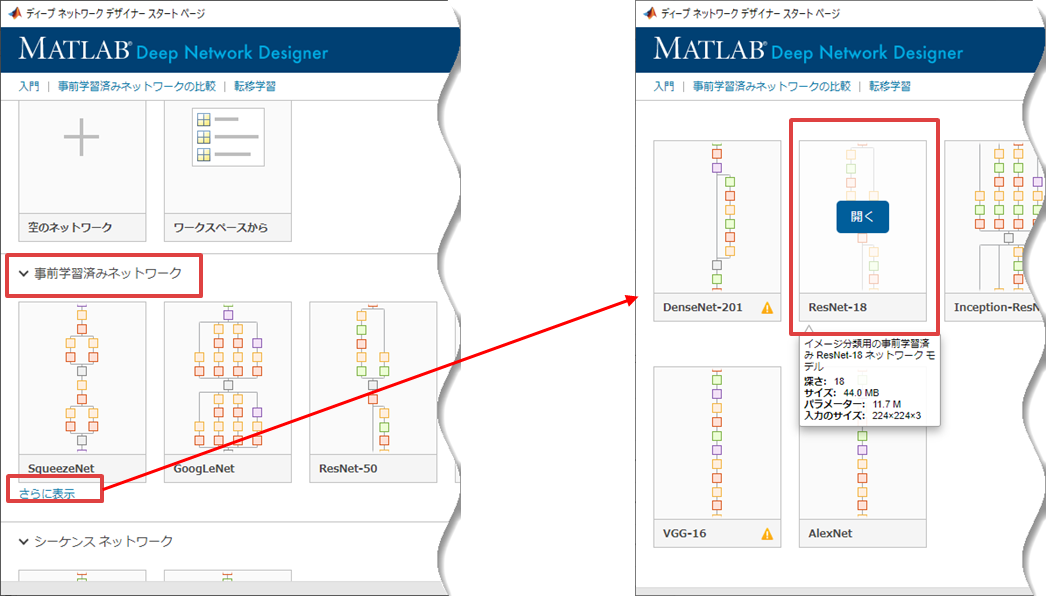

入力の「`data`」レイヤーをドラッグ＆ドロップで選択し、`delete`キーで削除 

   (学習済みの ResNet18 は 224 x 224 x 3 だが学習画像は 180 x 320 x 3 のため入力層を置き換える必要があるため)

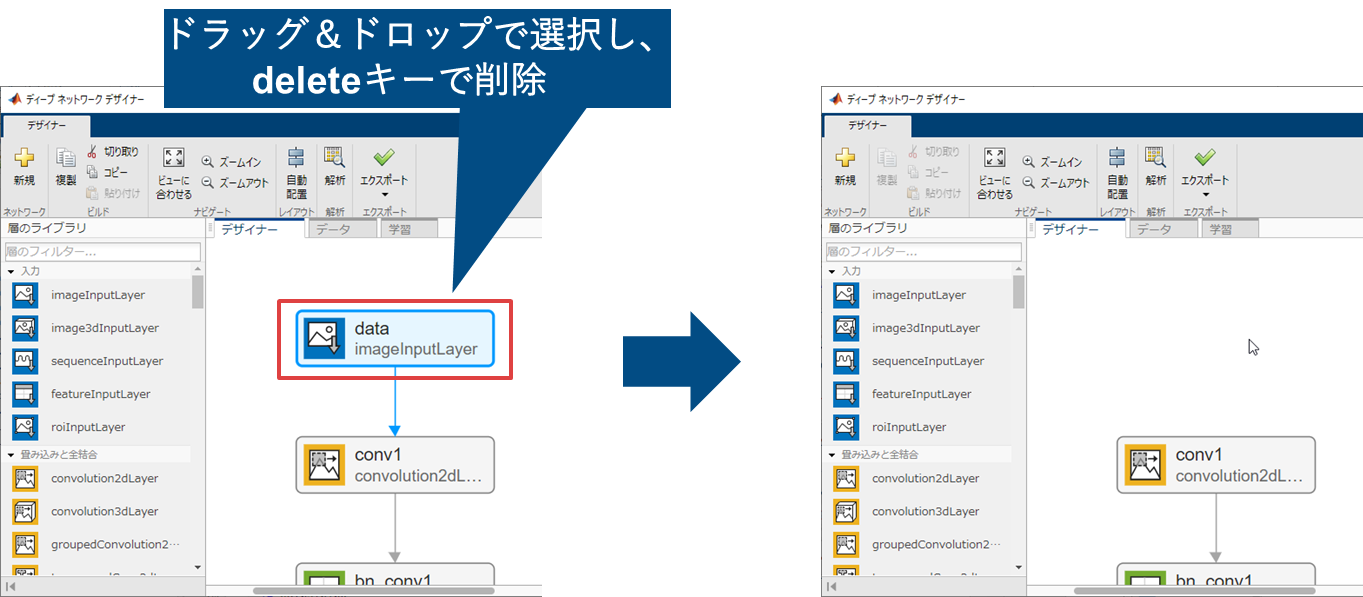

「層のライブラリ」の「入力」グループから「`imageInputLayer`」をドラッグ＆ドロップで追加

ドラッグ＆ドロップで線を引き出し「`conv1`」と接続

`imageInputLayer`のプロパティの「`InputSize`」を「`180,320,3`」に設定

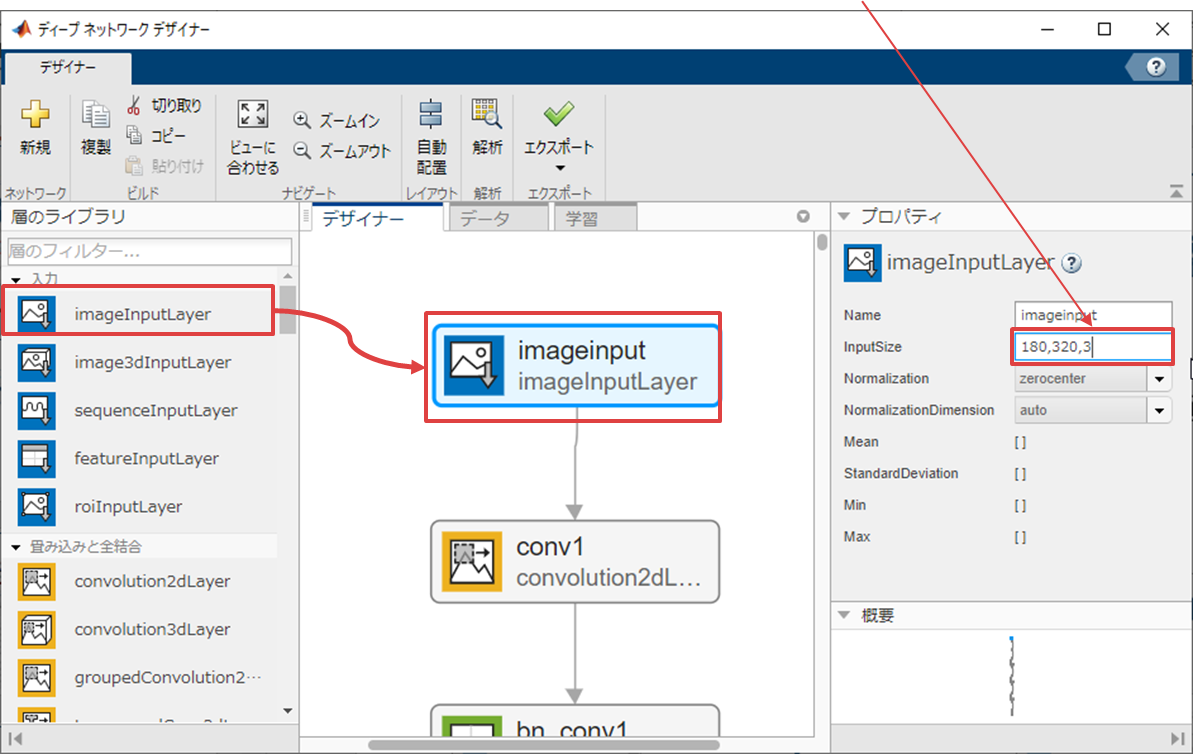

`fc1000`以降のレイヤーをドラッグ＆ドロップで選択し、`delete`キーで削除 

   (1000種類確率+softmaxによる分類から2種類の回帰に変更するため)

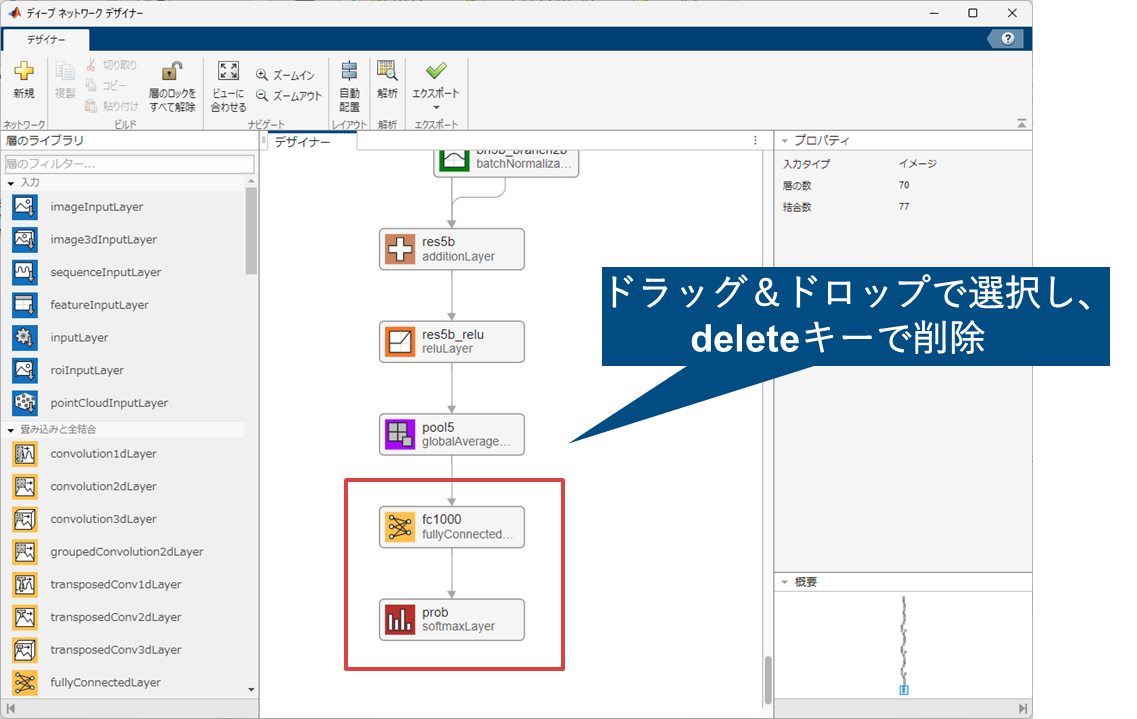

「層のライブラリ」の「畳み込みと全結合」から「`fullyConnectedLayer`」を追加

`fc`(fullyConnectedLayer)の「`OutputSize`**」**を「**2****」**に変更 (目標座標x,yの2変数なので)

`pool5`と`fc`を接続

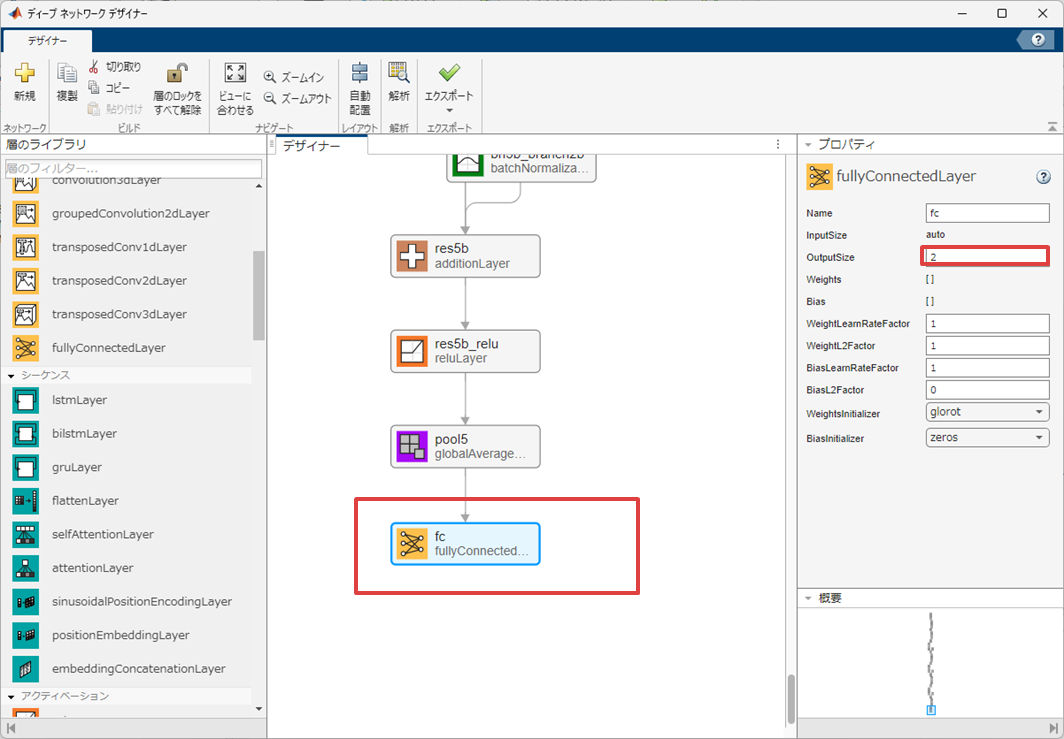

「解析」をクリックし、深層学習ネットワークアナライザーで整合性を確認

(エラーが0であればOK）

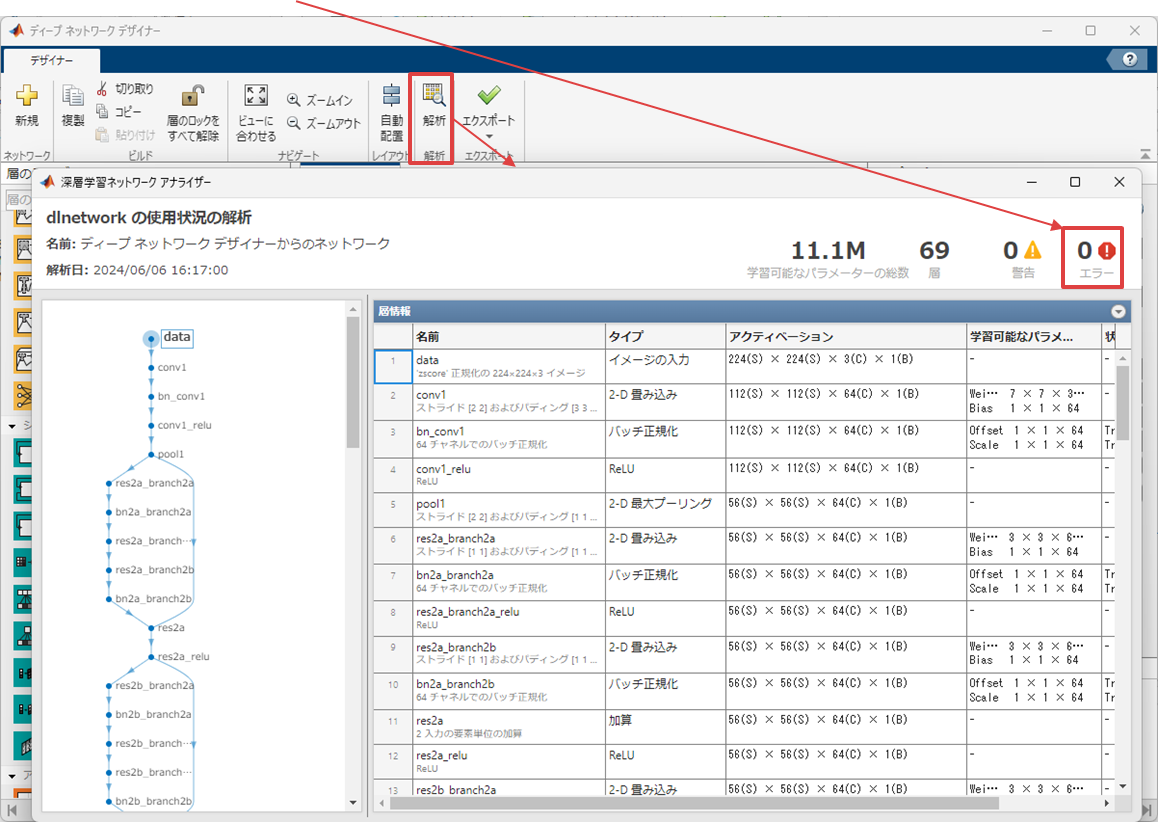

「エクスポート」→「エクスポート」をクリックしワークスペースに出力 

(デフォルトで`net_1`としてエクスポートされる)

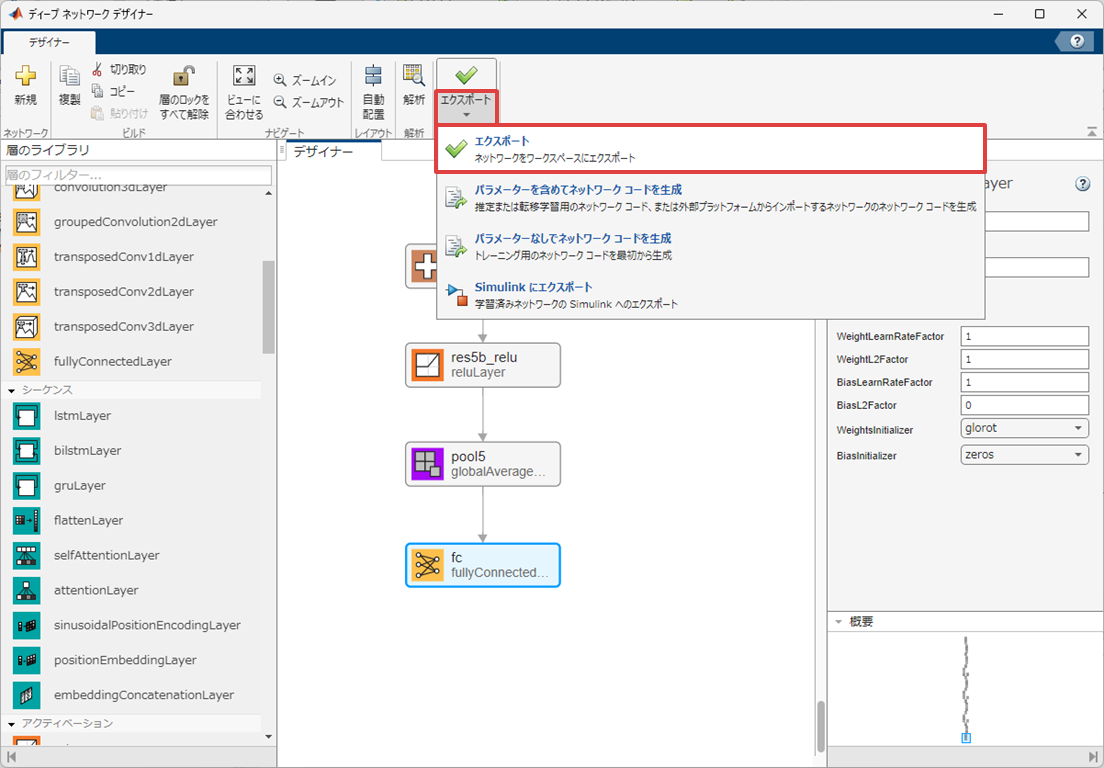

## 学習用のオプションを設定

`MaxEpochs`: 学習データセットを何回使うか。学習が収束していない場合は回数を増やす。

`InitialLearnRate`: 初期学習率。上げると学習が早くなるが発散しやすい。小さいと時間はかかるが精度が上がりやすい。

`LearnRateDropFactor`: 学習率を何倍にするか。

`LearnRateDropPeriod`: 何エポック経過したら学習率を下げるか。

options = trainingOptions('adam',...
    'MiniBatchSize',16,...
    'MaxEpochs',30,...
    'InitialLearnRate',1e-3,...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',20, ...
    'Shuffle','every-epoch',...
    'ResetInputNormalization',true,...
    'Verbose',true,...
    'Plots','training-progress');

## ネットワークの学習

if doTraining
    if exist('net_1','var')
        net = addLayers(net_1,regressionLayer("Name","regressionoutput"));
        net = connectLayers(net,net.Layers(end-1).Name,net.Layers(end).Name);
        lgraph_1 = layerGraph(net);
    end
    rng('default');
    trainedNet = trainNetwork(augTrainDs,lgraph_1,options);

    % 学習結果を保存
    save('mynet_new','trainedNet');
else
    load('mynet.mat');
end

## 学習に使っていないデータでテスト

testDs.reset;
annotatedImages = {};
for i = 1:testDs.numpartitions
    data = read(testDs);
    imdata = data{1};
    posGt = data{2};
    pos = predict(trainedNet,imdata);
    pos = pos .* (wh(1)/2) + wh(1)/2;
    posGt = posGt .* (wh(1)/2) + wh(1)/2;
    annotatedImages{i} = insertShape(data{1,1}, 'FilledCircle', [posGt 5],'Color','Green');
    annotatedImages{i} = insertShape(annotatedImages{i},'Line', [wh(1)/2, wh(2), posGt],...
        'LineWidth',3,'Color','Green');
    annotatedImages{i} = insertShape(annotatedImages{i}, 'FilledCircle', [pos 5],'Color','Red');
    annotatedImages{i} = insertShape(annotatedImages{i},'Line', [wh(1)/2, wh(2), pos],...
        'LineWidth',3,'Color','Red');
end
figure;
montage(annotatedImages);

## 次のステップ

[line_follower.slx](matlab:open('line_follower.slx')) を開いて学習済みのネットワークを使ってライントレースを実行する

## [メニューに戻る](matlab:open('workshopMenu_jp.mlx'))

function data = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.

data = cell(size(A));
for ii = 1:size(A,1)
    I = A{ii,1};
    pos = A{ii,2};
    sz = size(I);

    %if numel(sz) == 3 && sz(3) == 3
    %    I = jitterColorHSV(I,...
    %        'Contrast',[0.2 0.8],...
    %        'Hue',0.05,...
    %        'Saturation',0.1,...
    %        'Brightness',0.2);
    %end

    % Randomly flip image.
    tform = randomAffine2d('XReflection',true);
    rout = affineOutputView(sz,tform,'BoundsStyle','centerOutput');
    I = imwarp(I,tform,'OutputView',rout);

    % Apply same transform to boxes.
    pos = tform.transformPointsForward(pos);

    data(ii,:) = {I, pos};
end
end

*Copyright 2021 The MathWorks, Inc.*